% create a string array

Stringarray =["A6","A9","A12","A15","A18","A21","A24"];
% or
A= "A"+(6:3:24);

A cell array is a data type with indexed data containers called cells, where each cell can contain any type of data.

a1=(11:20);
a2=5;
a3=10;
a4=(12:-2:2);
a12="This is valdo";
a13 = rand(5,6);
a14 = (11:3:32)';
a15=eye(3)

a15 =      1     0     0
     0     1     0
     0     0     1



CA ={a1,a2,a3,a4;a12,a13,a14,a15};

display element 2, 4 of the array

disp(CA(2,4));

    {3×3 double}



% display the content of 2,4 
disp(CA{2,4});

     1     0     0
     0     1     0
     0     0     1



load nci60.mat
% extract sub table 
PT = nci60(:,["x15938" "x9634" "x21830" "y"]);
disp(PT)

    x15938    x9634    x21830      y  
    ______    _____    ______    _____

     8.29      7.95     5.42      6.18
     3.14      7.14     3.35      3.44
     3.06      7.25        3     -0.58
     3.64       6.9     5.86     -0.09
     8.24      9.72     6.03      6.26
      3.1      3.65     3.38      0.35
     3.09      6.21     3.51     -1.53
     3.11      6.39     3.62     -1.53
     3.11      7.35     3.44        -1
     3.15      5.95     5.18     -1.77
     3.09      8.17     4.11      2.01
     6.94      5.64      3.5     -3.57
     5.05      7.83     3.77      5.26
     3.74         8     3.72       3.8
     5.29      8.25     4.32      5.01
     6.16      8.33     4.01       5.9
      7.6      7.15     3.66     -2.88
     6.88      7.32     4.36      5.85
     3.34      6.08     3.55     -2.48
     3.48      5.05     3.66     -2.75
     3.64      7.14      3.5      1.72
     3.71      5.97     3.62     -3.23
     3.34      6.57     3.57      0.63
      3.2       5.4     

% create the following table row vector uno
uno = [0,1,2];
% create column vector vn with the first 3 natural no
vn=[0,1,2];
% or
vn =(0:2)';

% cerate a 2 by 3 matrix with the first 6 natural no
mn =[0,1,2;3,4,5]

mn =      0     1     2
     3     4     5



% create evenly spaced vector from interval [1 15]
nd =1:2:15;

% create 2 by 1 string array ot
ot=["Jhone","Do"];
% create a 2 by 1 column vector with first name jhone and second name Do
vt = ["Jhone";"Do"];

% create a random 3 by 2 matrix named A with see vale 22
rng(22)
A= rand(3,2);

% extraction or selection practice

A(3,2)

ans = 0.3389

A(3,:)

ans =     0.4205    0.3389


A(2:3,1:2)

ans =     0.4817    0.1712
    0.4205    0.3389


A([1 3] ,:)

ans =     0.2085    0.8592
    0.4205    0.3389


A(end,2)

ans = 0.3389

A(end:-1:1,2) % reverse of last row

ans =     0.3389
    0.1712
    0.8592


% character
ch= 'Melaku';
disp(ch);

Melaku


disp(double(ch)); % display ascii code for each number

    77   101   108    97   107   117



disp(double(ch)+1); % display each ascii + 1

    78   102   109    98   108   118



disp(char('Melaku'+1));% display char next to each position

Nfmblv


% string represent in double qoute
Name = "Melaku";
disp(Name);

Melaku


%disp(Name)+1;
disp("Melaku"+1);

Melaku1


% cell array
txt= "Bonjorino";
b= rand(3,2)

b =     0.2705    0.8120
    0.6910    0.0105
    0.2204    0.5612


c =[11 22 33]'

c =     11
    22
    33


cm ={1,2,3;txt,b,c}

cm = 2×3 cell array
    {[          1]}    {[       2]}    {[       3]}
    {["Bonjorino"]}    {3×2 double}    {3×1 double}


% acess the cell and the value inside
cm(2,3);
cm{2,2};


% structure data type st with six elemet

st = struct;
st.a=1;
st.b =2;
st.c=3;
st.d ="Bongorino";
st.e = rand(3,2);
st.f =[11;22;33];
disp(st);

    a: 1
    b: 2
    c: 3
    d: "Bongorino"
    e: [3×2 double]
    f: [3×1 double]



% extract data from struct
% access the third element
st.c

ans = 3

% extract the second column of fifith element
st.e(:,2)

ans =     0.0061
    0.7720
    0.9578


% reading Tables, the first argument is the filename,
X= readtable("Firm.xlsx", Sheet='data',Range='A1:J108',ReadRowNames=true)

X = 107×9 table
                Surname             Name           Gender     BirthDate     Education    Wage    CommutingTime    SmartWorkHours    Seniority
             _____________    _________________    ______    ___________    _________    ____    _____________    ______________    _________

    P0211    {'BASILICO' }    {'TIZIANA'      }    {'F'}     16-Jun-1991      {'A'}      1877         27                10             11    
    P0212    {'BONINO'   }    {'PAOLO'        }    {'M'}     01-Jul-1993      {'B'}      2375         35                12              8    
    P0213    {'GRI'      }    {'ALBERTO'      }    {'M'}     19-Oct-1987      {'C'}      2450         39                16             11    
    P0214    {'BARBIERI' }    {'ROSSANA'      }    {'F'}     28-Jan-1992      {'B'}      2037         16                 6              7    
    P0215    {'PRENNA'   }    {'FEDERICA'     }    {'F'}     22-Jan-1966      {'C'}      3893         23                 8         

Firm=readtable("Firm.xlsx", Sheet='data',Range='A1:J108',ReadRowNames=false)

Firm = 107×10 table
      Code          Surname             Name           Gender     BirthDate     Education    Wage    CommutingTime    SmartWorkHours    Seniority
    _________    _____________    _________________    ______    ___________    _________    ____    _____________    ______________    _________

    {'P0211'}    {'BASILICO' }    {'TIZIANA'      }    {'F'}     16-Jun-1991      {'A'}      1877         27                10             11    
    {'P0212'}    {'BONINO'   }    {'PAOLO'        }    {'M'}     01-Jul-1993      {'B'}      2375         35                12              8    
    {'P0213'}    {'GRI'      }    {'ALBERTO'      }    {'M'}     19-Oct-1987      {'C'}      2450         39                16             11    
    {'P0214'}    {'BARBIERI' }    {'ROSSANA'      }    {'F'}     28-Jan-1992      {'B'}      2037         16                 6              7    
    {'P0215'}    {'PRENNA'   }    {'FEDERICA'     }    {'F'}     22-Jan-1966      {'C'}      3893      

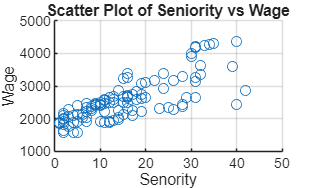

% Scatter plot for Seniority Vs Wage
% Prepare the data for the scatter plot
hold on; % Hold the current plot
scatter(X.Seniority,X.Wage)
xlabel("Senority")
ylabel("Wage");
title("Scatter Plot of Seniority vs Wage");
grid on;

% extract the first 5 values of wage from the firm table imported as row
% names =0 put in the table named Firm
Firm= Y.Wage(1:5)

Firm =         1877
        2375
        2450
        2037
        3893


% or we can make it 
Y(1:5,7)

ans = 5×1 table
    Wage
    ____

    1877
    2375
    2450
    2037
    3893


% or
Y{1:5,"Wage"}

ans =         1877
        2375
        2450
        2037
        3893


% extract the first 5 values from both wage and seniority
Y{1:5,["Wage" "Seniority"]}

ans =         1877          11
        2375           8
        2450          11
        2037           7
        3893          30


% or
Y(1:5,[7 10])

ans = 5×2 table
    Wage    Seniority
    ____    _________

    1877       11    
    2375        8    
    2450       11    
    2037        7    
    3893       30    


% extract subject 
X("P0219",:)

ans = 1×9 table
                Surname          Name       Gender     BirthDate     Education    Wage    CommutingTime    SmartWorkHours    Seniority
             _____________    __________    ______    ___________    _________    ____    _____________    ______________    _________

    P0219    {'DE SCALZI'}    {'DAVIDE'}    {'M'}     03-Oct-1999      {'B'}      2016         19                4               2    


% extract two row values
X(["P0219" "P0476"],:)

ans = 2×9 table
                Surname          Name       Gender     BirthDate     Education    Wage    CommutingTime    SmartWorkHours    Seniority
             _____________    __________    ______    ___________    _________    ____    _____________    ______________    _________

    P0219    {'DE SCALZI'}    {'DAVIDE'}    {'M'}     03-Oct-1999      {'B'}      2016         19                 4              2    
    P0476    {'FAVELLA'  }    {'FELICE'}    {'M'}     25-Sep-1991      {'C'}      2338         21                12              7    


X({'P0219' 'P0476'},:)

ans = 2×9 table
                Surname          Name       Gender     BirthDate     Education    Wage    CommutingTime    SmartWorkHours    Seniority
             _____________    __________    ______    ___________    _________    ____    _____________    ______________    _________

    P0219    {'DE SCALZI'}    {'DAVIDE'}    {'M'}     03-Oct-1999      {'B'}      2016         19                 4              2    
    P0476    {'FAVELLA'  }    {'FELICE'}    {'M'}     25-Sep-1991      {'C'}      2338         21                12              7    


% EXTRACT FROM firm all women
Womendata = X(X.Gender=="F",:)

Womendata = 46×9 table
                Surname               Name           Gender     BirthDate     Education    Wage    CommutingTime    SmartWorkHours    Seniority
             ______________    __________________    ______    ___________    _________    ____    _____________    ______________    _________

    P0211    {'BASILICO'  }    {'TIZIANA'       }    {'F'}     16-Jun-1991      {'A'}      1877         27                10             11    
    P0214    {'BARBIERI'  }    {'ROSSANA'       }    {'F'}     28-Jan-1992      {'B'}      2037         16                 6              7    
    P0215    {'PRENNA'    }    {'FEDERICA'      }    {'F'}     22-Jan-1966      {'C'}      3893         23                 8             30    
    P0217    {'MAROVINO'  }    {'ELISABETTA'    }    {'F'}     14-Oct-1966      {'A'}      1893         29                 6             12    
    P0220    {'BARBIERI'  }    {'LAURA'         }    {'F'}     10-Mar-1999      {'B'}      1635         45      

% select all girl with education level B
X(X.Education=="B" & X.Gender=="F" ,:)

ans = 15×9 table
                 Surname                  Name              Gender     BirthDate     Education    Wage    CommutingTime    SmartWorkHours    Seniority
             ________________    _______________________    ______    ___________    _________    ____    _____________    ______________    _________

    P0214    {'BARBIERI'    }    {'ROSSANA'            }    {'F'}     28-Jan-1992      {'B'}      2037         16                 6              7    
    P0220    {'BARBIERI'    }    {'LAURA'              }    {'F'}     10-Mar-1999      {'B'}      1635         45                16              2    
    P0225    {'SOFFIETTI'   }    {'MARINA ANGELA'      }    {'F'}     12-Jun-1975      {'B'}      2226         47                14             11    
    P0250    {'RIVOIRA'     }    {'MARILENA'           }    {'F'}     03-Oct-1996      {'B'}      1760         18                 6              3    
    P0255    {'CARPINELLO'  }    {'NADIA'              }    {'F'}     18-Jun

% select female with education level b or male with wage grater than 4000
X((X.Gender=="F" & X.Education=="B") |(X.Gender=="M" & X.Wage>4000),:)

ans = 20×9 table
                 Surname                  Name              Gender     BirthDate     Education    Wage    CommutingTime    SmartWorkHours    Seniority
             ________________    _______________________    ______    ___________    _________    ____    _____________    ______________    _________

    P0214    {'BARBIERI'    }    {'ROSSANA'            }    {'F'}     28-Jan-1992      {'B'}      2037         16                 6              7    
    P0220    {'BARBIERI'    }    {'LAURA'              }    {'F'}     10-Mar-1999      {'B'}      1635         45                16              2    
    P0224    {'VELARDI'     }    {'ALFREDO'            }    {'M'}     09-Feb-1961      {'B'}      4354         21                10             40    
    P0225    {'SOFFIETTI'   }    {'MARINA ANGELA'      }    {'F'}     12-Jun-1975      {'B'}      2226         47                14             11    
    P0250    {'RIVOIRA'     }    {'MARILENA'           }    {'F'}     03-Oct

% select all income greater than or equal to 3000 and less than 3500
X(X.Wage>=3000 & X.Wage<3500,:)

ans = 12×9 table
                Surname                Name              Gender     BirthDate     Education    Wage    CommutingTime    SmartWorkHours    Seniority
             _____________    _______________________    ______    ___________    _________    ____    _____________    ______________    _________

    P0222    {'RIVA'     }    {'GIANLUCA'           }    {'M'}     08-Sep-1985      {'B'}      3370         26                12             16    
    P0301    {'LUPARIA'  }    {'GUALTIERO'          }    {'M'}     17-Oct-1976      {'C'}      3176         19                 6             22    
    P0314    {'ROSSO'    }    {'PAOLO'              }    {'M'}     16-Mar-1965      {'B'}      3386         28                10             24    
    P0315    {'ROSSO'    }    {'MARCO'              }    {'M'}     07-Jul-1985      {'B'}      3262         15                 4             16    
    P0317    {'BARLETTA' }    {'ELISABETTA GIOVANNA'}    {'F'}     05-Aug-1965      {'B'}     

% Excersice 1.9
% display record where surname start with "CAS"
na= "CAS";
endwithna="LA";
Y(startsWith(X.Surname,na),:)

ans = 4×10 table
      Code          Surname          Name       Gender     BirthDate     Education    Wage    CommutingTime    SmartWorkHours    Seniority
    _________    ______________    _________    ______    ___________    _________    ____    _____________    ______________    _________

    {'P0287'}    {'CASETTA'   }    {'CATIA'}    {'F'}     21-Nov-1973      {'B'}      2629         24                6              19    
    {'P0472'}    {'CASTELLANO'}    {'PAOLA'}    {'F'}     02-Mar-1993      {'C'}      2407         33                8               5    
    {'P0508'}    {'CASELLA'   }    {'LAURA'}    {'F'}     28-Jul-1983      {'C'}      2675         16                8              15    
    {'P0510'}    {'CASUCCI'   }    {'PAOLA'}    {'F'}     25-Apr-1995      {'C'}      2287         15                4               3    


Y(endsWith(X.Name,endwithna),:)

ans = 11×10 table
      Code           Surname                  Name              Gender     BirthDate     Education    Wage    CommutingTime    SmartWorkHours    Seniority
    _________    ________________    _______________________    ______    ___________    _________    ____    _____________    ______________    _________

    {'P0225'}    {'SOFFIETTI'   }    {'MARINA ANGELA'      }    {'F'}     12-Jun-1975      {'B'}      2226         47                14             11    
    {'P0246'}    {'ORLANDI'     }    {'ALBERTO LUCA NICOLA'}    {'M'}     24-Jun-1999      {'B'}      1812         28                10              2    
    {'P0249'}    {'FERRERO'     }    {'DANIELA'            }    {'F'}     13-Sep-1974      {'A'}      2287         28                 6             26    
    {'P0252'}    {'ROSSI'       }    {'MARIA PAOLA'        }    {'F'}     19-Sep-1968      {'C'}      3988         29                 8             30    
    {'P0285'}    {'PARRA SAIANI'}    {'PAOLA'      

% Display the name start with R and end with O
startr="R";
endwithO="O";
Y(startsWith(X.Name,startr)& endsWith(X.Name,endwithO),:)

ans = 4×10 table
      Code             Surname              Name        Gender     BirthDate     Education    Wage    CommutingTime    SmartWorkHours    Seniority
    _________    ___________________    ____________    ______    ___________    _________    ____    _____________    ______________    _________

    {'P0233'}    {'ROSSI'          }    {'RICCARDO'}    {'M'}     14-May-1991      {'A'}      1931         17                 4             13    
    {'P0254'}    {'NOVELLO'        }    {'ROBERTO' }    {'M'}     17-Nov-1998      {'A'}      1559         37                14              2    
    {'P0411'}    {'MOURGLIA LESLEY'}    {'ROBERTO' }    {'M'}     26-Jun-1997      {'A'}      1899         14                 4              7    
    {'P0477'}    {'POZZI'          }    {'ROBERTO' }    {'M'}     05-Jun-1989      {'C'}      2423         25                 8              9    


surs ="R";
sure ="O" | "A";
Y(startsWith(X.Name,surs) & endsWith(X.Name,sure),:)

ans = 8×10 table
      Code             Surname              Name        Gender     BirthDate     Education    Wage    CommutingTime    SmartWorkHours    Seniority
    _________    ___________________    ____________    ______    ___________    _________    ____    _____________    ______________    _________

    {'P0214'}    {'BARBIERI'       }    {'ROSSANA' }    {'F'}     28-Jan-1992      {'B'}      2037         16                 6              7    
    {'P0231'}    {'GRILLO'         }    {'ROBERTA' }    {'F'}     30-Jun-1997      {'A'}      1562         17                 4              5    
    {'P0233'}    {'ROSSI'          }    {'RICCARDO'}    {'M'}     14-May-1991      {'A'}      1931         17                 4             13    
    {'P0254'}    {'NOVELLO'        }    {'ROBERTO' }    {'M'}     17-Nov-1998      {'A'}      1559         37                14              2    
    {'P0307'}    {'CARLI'          }    {'ROSSANA' }    {'F'}     27-Sep-1981      {'B'}      2653  

srs ="P";
sre = ["O", "A"];
len =7;
Y(startsWith(Y.Surname,srs) & endsWith(Y.Surname,sre) & strlength(Y.Surname)<=len,:)

ans = 2×10 table
      Code        Surname          Name         Gender     BirthDate     Education    Wage    CommutingTime    SmartWorkHours    Seniority
    _________    __________    _____________    ______    ___________    _________    ____    _____________    ______________    _________

    {'P0215'}    {'PRENNA'}    {'FEDERICA' }    {'F'}     22-Jan-1966      {'C'}      3893         23                 8             30    
    {'P0277'}    {'PATRIA'}    {'ALEXANDRE'}    {'M'}     09-Aug-1967      {'C'}      4209         30                10             31    
